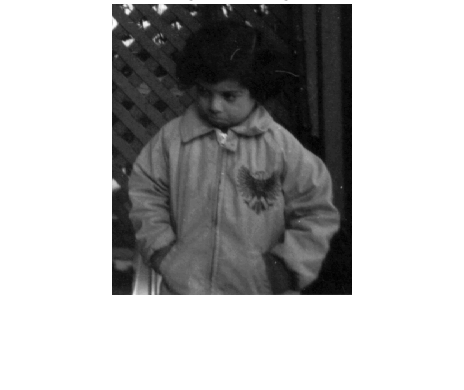

% EX 2. Implementing histogram equalisation algorithmically
pout = imread('pout.tif');
imshow(pout,[]);
title("original image");

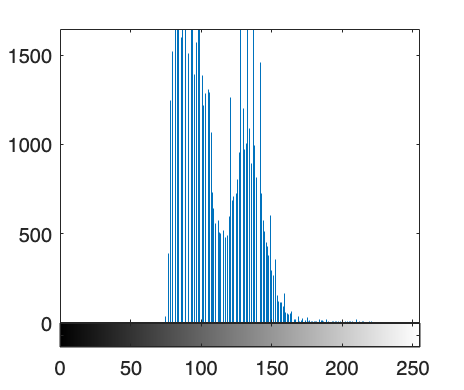


% Create a 256-element vector
histogram = imhist(pout);
imhist(pout);

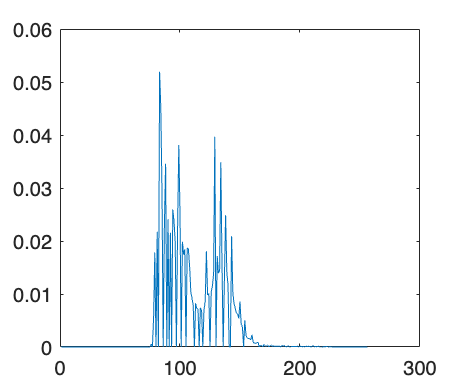



% Normalize the histogram
numPixels = numel(pout);
normalizedHistogram = histogram / numPixels;
plot(normalizedHistogram);

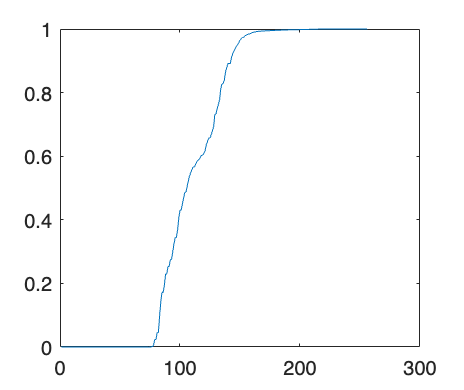


% Calculate the cumulative distribution function (CDF)
cdf = cumsum(normalizedHistogram);
plot(cdf);

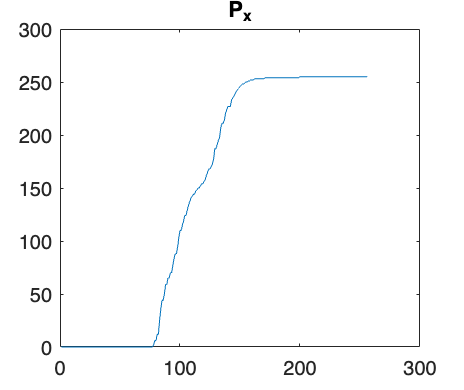


% Calculate the transform function
P_x = uint8(255 * cdf);
plot(P_x);
title('P_x')

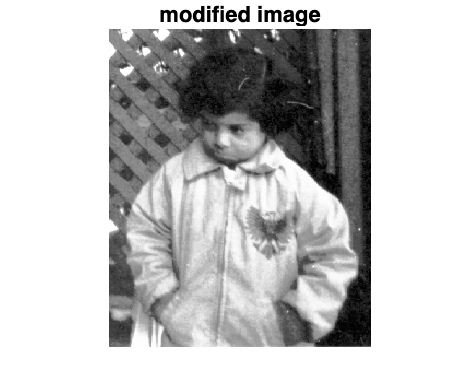


% Apply histogram equalization using the transform function
% equalizedImage = T(pout + 1);  % '+1' because MATLAB uses 1-based indexing
pout_equalized = P_x(pout+1);


% Display the equalized image
imshow(pout_equalized, []);
title("modified image");

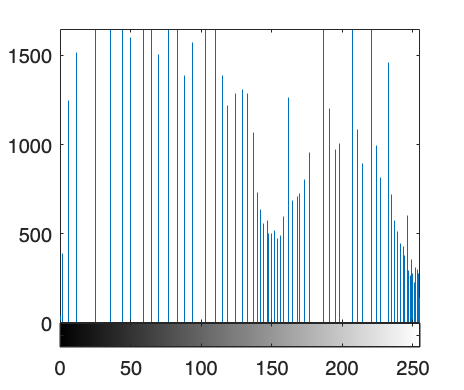


imhist(pout_equalized);

histogram_new = imhist(pout);

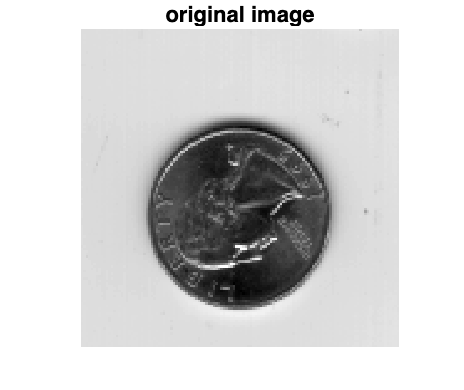

% EX 3. Implementing histogram specification algorithmically
load('quarter.mat')
imshow(quarter,[]);
title("original image")

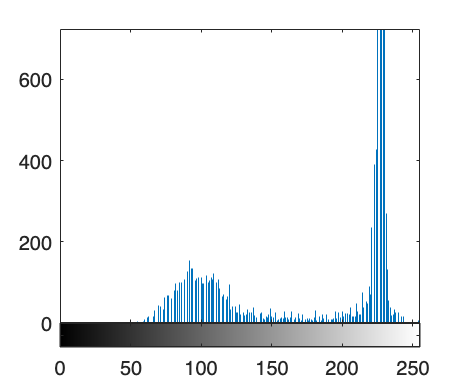

imhist(quarter);

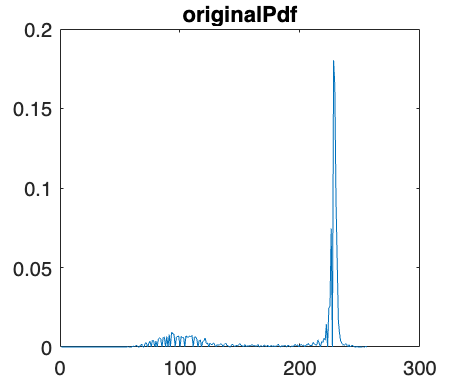


% Determine suitable values for upperlimit_in and upperlimit_out
upperlimit_in = 160; % Adjust as needed
upperlimit_out = 180; % Adjust as needed

% Compute the original PDF and CDF
originalHistogram = imhist(quarter);

originalPdf = originalHistogram / numel(quarter);
plot(originalPdf);
title("originalPdf");

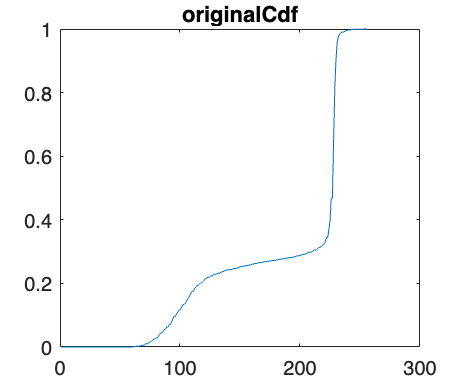


originalCdf = cumsum(originalPdf);
plot(originalCdf);
title("originalCdf");



% Compute the target PDF and CDF
N_below = sum( quarter <= upperlimit_in, "all");
N_above = sum( quarter >  upperlimit_in, "all");
disp('Fraction of pixels below upperlimit_in:')

Fraction of pixels below upperlimit_in:


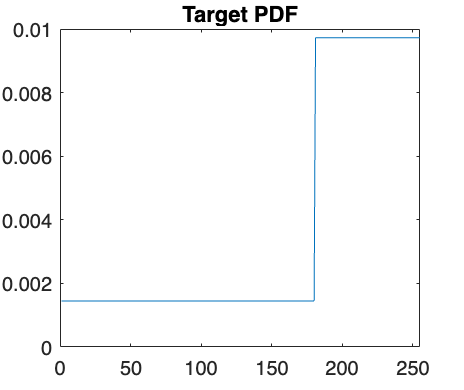

ratio = N_below / (N_above + N_below);

targetPdf = zeros(256, 1);
targetPdf(1:upperlimit_out    ) = ratio / upperlimit_out;
targetPdf(upperlimit_out+1:end) = (1-ratio) / (256-upperlimit_out);
plot(targetPdf);
title("Target PDF");
xlim([0, 255]);

disp(["The sum of target pdf is:",sum(targetPdf,"all")]);

    "The sum of target pdf is:"    "1"



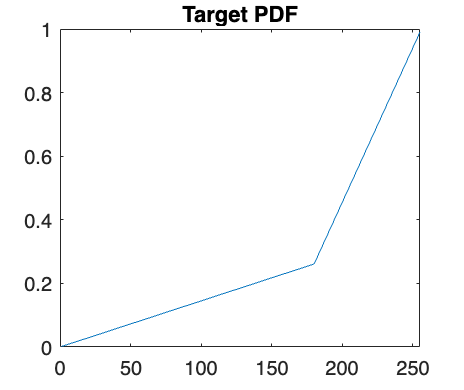


targetCdf = cumsum(targetPdf);
plot(targetCdf);
title("Target PDF");
xlim([0, 255]);

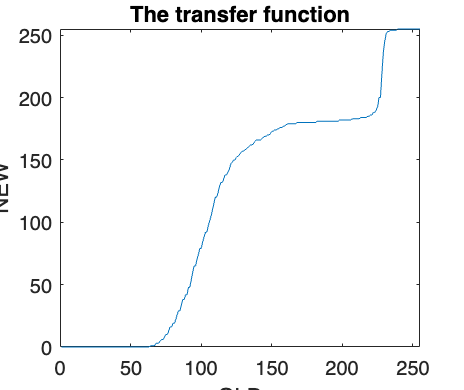



% Calculate the transfer function
transferFunction = zeros(256, 1);
for i = 1:256
    [~, index] = min(abs(targetCdf - originalCdf(i)));
    transferFunction(i) = index - 1;
end

% plot the transform function
plot(transferFunction) % The transfer function
title("The transfer function")
xlim([0 255])
ylim([0 255])
xlabel("OLD")
ylabel("NEW")

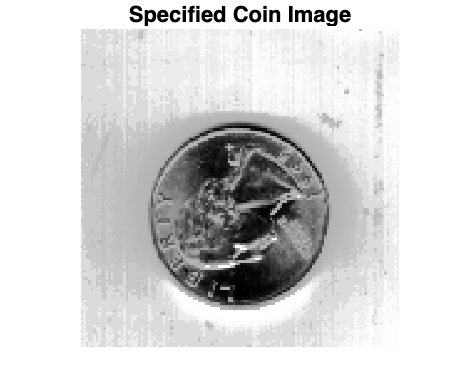



% Apply histogram specification using the transfer function
specifiedCoin = transferFunction(quarter + 1); % '+1' for 1-based indexing

% Display the specified coin image
imshow(specifiedCoin, []);
title('Specified Coin Image');

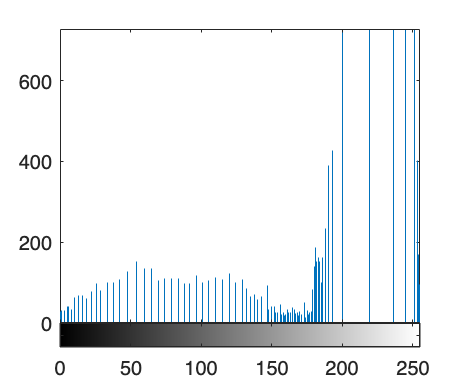


imhist(uint8(specifiedCoin));